# **Chargement de la base de données**

**Objectif :** Charger les images de la base d'entraînement et connaître le nombre d'images par catégorie.

Les images sont rangées dans plusieurs dossiers, chaque dossier correspondant à un type de défaut.

La fonction `imageDatastore` permet de charger l'ensemble des images sans avoir à les ouvrir individuellement.

root = fullfile(pwd, 'data', 'train');

imds = imageDatastore(root, 'IncludeSubfolders', true, 'LabelSource','foldernames');
countEachLabel(imds)

ans = 6×2 table
         Label         Count
    _______________    _____

    crazing             240 
    inclusion           240 
    patches             240 
    pitted_surface      240 
    rolled_in_scale     240 
    stratches           240 


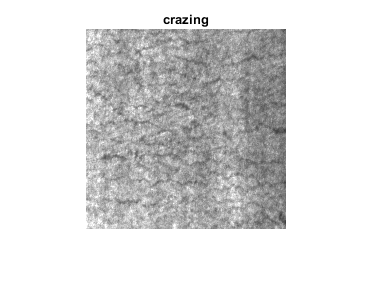

I = readimage(imds, 1);

imshow(I), title(string(imds.Labels(1)))

**Résultats et observations :**

Le programme affiche le nombre d'images disponibles pour chaque catégorie de défaut.

Cette étape permet de vérifier la répartition des images et de repérer un éventuel déséquilibre entre les classes.

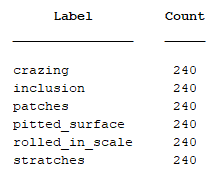

# **Prétraitement des images**

**Conversion en niveaux de gris**

**Objectif :** Convertir les images couleur en niveaux de gris pour faciliter leur analyse.

Cette opération permet de travailler uniquement sur l'intensité lumineuse des pixels, sans tenir compte des couleurs.

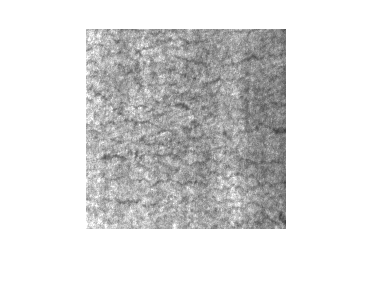

Igray = rgb2gray(I);
imshow(Igray)

**3.b. Filtrage spatial**

**Objectif :** Réduire le bruit présent sur les images à l'aide d'un filtre médian.

Le filtre médian 3×3 remplace chaque pixel par la valeur médiane de ses voisins. Cela permet de supprimer certains pixels parasites tout en préservant relativement bien les contours.

**Observation :** Le filtrage peut rendre l'image plus homogène. Son efficacité dépend du bruit présent sur l'image et il peut aussi supprimer certains petits détails.

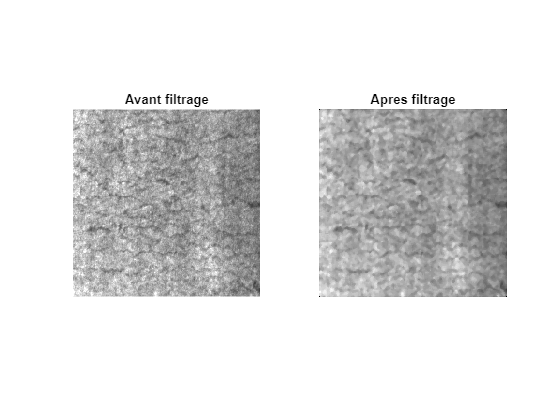


%% Filtrage spatial

Ifilt = medfilt2(Igray, [3 3]);

figure;
subplot(1, 2, 1);
imshow(Igray);
title('Avant filtrage');

subplot(1, 2, 2);
imshow(Ifilt);
title('Apres filtrage');

**3.c. Normalisation et redimensionnement**

**Objectif :** Uniformiser les dimensions des images avant leur utilisation dans un modèle d'intelligence artificielle.

La fonction `imresize` permet de redimensionner les images en 224 × 224 pixels.

Cette opération permet d'obtenir des images ayant toutes les mêmes dimensions, ce qui facilite leur utilisation lors de l'apprentissage.

**5. Documentation de la base de données**

**Objectif :** Présenter les caractéristiques de la base d'images utilisée pour le projet.

**Base de données :** NEU Surface Defect Database.

**Composition :**

- 6 catégories de défauts.

- 240 images d'entraînement par catégorie.

- 1 440 images d'entraînement au total.

- Dimensions originales : 200 × 200 pixels.

- Dimensions utilisées pour l'apprentissage : 224 × 224 pixels.

**Catégories :**

- Crazing : craquelures.

- Inclusion : inclusions de matière.

- Patches : zones irrégulières.

- Pitted surface : piqûres de surface.

- Rolled-in scale : défauts liés à la calamine.

- Scratches : rayures.

**Traitements appliqués :**

- Conversion en niveaux de gris.

- Filtrage médian 3×3.

- Redimensionnement en 224 × 224 pixels.

- Augmentation des données par rotation et translation.

**Difficultés rencontrées :**

- Les images étant déjà en niveaux de gris, la conversion n'apporte pas de différence visible.

- Le filtrage médian réduit certaines variations de texture, mais peut atténuer les détails fins.

**6. Premières analyses statistiques**

**Objectif :** Étudier la répartition des intensités lumineuses d'une image.

Nous calculons trois caractéristiques :

- **Moyenne :** représente la luminosité moyenne de l'image.

- **Écart-type :** indique la dispersion des intensités lumineuses.

- **Histogramme :** représente le nombre de pixels pour chaque niveau de gris.

Ces analyses permettent de mieux comprendre les caractéristiques des images et de repérer d'éventuelles anomalies de luminosité.

# Chapitre 3 — Détection supervisée

## 1. Principe de l'apprentissage supervisé

Objectif : Entraîner une intelligence artificielle à reconnaître automatiquement les différents défauts présents sur les images.

L'apprentissage supervisé consiste à fournir au modèle des images accompagnées de leur catégorie.

Le modèle apprend à reconnaître les caractéristiques de chaque défaut pour pouvoir ensuite classifier une nouvelle image.

Dans notre projet, nous utilisons six catégories de défauts.

## 2. Réseaux de neurones

Un réseau de neurones est composé de plusieurs couches qui permettent d'analyser les données.

Pour les images, on utilise des réseaux de neurones convolutionnels (CNN), capables de reconnaître des formes, des contours et des textures.

## 3. Transfert d'apprentissage

Le transfert d'apprentissage consiste à utiliser un réseau déjà entraîné et à l'adapter à notre base de données.

Nous utiliserons **ResNet-18**, comme indiqué dans le cours, afin de reconnaître nos six catégories de défauts.